# Position Stepper Motor Functions

This script creates the code for a set of functions to position control a standard stepper motor attached to a microstepping driver controller from two digital pins on a standard Arduino-class micro controller

- Arduino PWN pin6 to R208 step input(yellow)

- Arduino pin7 directly to dir-input(orange)

- Arduino 5V DC to 5V DC for opticle isolator (blue)

- Arduino GND to R208 logic ground(white wire)

- Use built-in LED on pin13 for blinky robot alive light

Eliyahu Suskind and Dowling Wong, Revision 2, 2/5/22

clc     %clear command window
clear   %clear MATLAB workspace

### Set up Robot control system(code runs once)

%Create arduino and arduino-pin ref objects
[robotArduino, blinkLED] = setupArduino('COM9');

Warning! Downloading may take a seconds
Warning! Stepper moving!



%ACTmoveStepMotor(arduinoName, numberOfSteps, direction, speed)
pause(1.0);
beep;

%configure test loop to collect n data points.
nTest = input( ...
    'Enter number of servo test positions, followed by enter: ' ...
    );

%create a variable to hold experimental position data
positionData = zeros(nTest,2);
r = rateControl(0.25);
reset(r);


### Run robot control loop(code that runs over and over)

controlFlag = 1;
oldAngle = 0;
while(controlFlag < nTest+1)
    commandAngle = SENSE();
    [steps, direction] = THINK(oldAngle, commandAngle);
    ACTmoveStepMotor(robotArduino, steps, direction, 0.1);
    oldAngle = commandAngle;

    positionData(controlFlag, 1)= input('Enter actual position degrees: ');
    positionData(controlFlag, 2)= commandAngle;
    Blink(robotArduino, blinkLED, 1);
    waitfor(r);
    controlFlag = controlFlag+1;
end

### Mission Data Processing

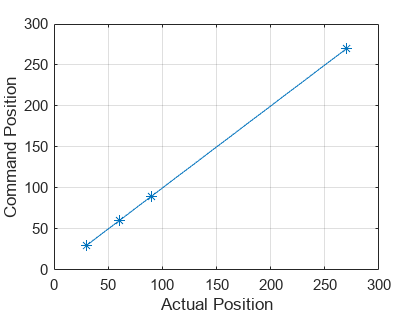

%position data vs. actual position
 plot (positionData(:,1), positionData(:,2), '-*')
 xlabel('Actual Position')
 ylabel('Command Position')
 grid

save positionServo.dat positionData -ascii

### Clean and Shutdown

Clean and shutdown by returning to neutral angle, clearing command window and arduino obj, and beeping

[steps, direction] = THINK(oldAngle, 0);
ACTmoveStepMotor(robotArduino, steps, direction, 0.1);
clc
disp('Arduino stepper program has ended');

Arduino stepper program has ended


clear robotArduino
beep

### Robot Functions

function [robotArduino, blinkLED] = setupArduino(COMPORT)

    robotArduino = arduino(COMPORT, 'Uno', 'Libraries', 'I2C');
    %create a global arduino object
    disp('Warning! Downloading may take a seconds');

    blinkLED = 'D13';
    configurePin(robotArduino, blinkLED, 'DigitalOutput');
    %pin13 as LED

    stepPin = 'D6';
    configurePin(robotArduino, stepPin, 'DigitalOutput');
    %pin6 as step pulse

    dirPin = 'D7';
    configurePin(robotArduino, dirPin, 'DigitalOutput');
    %pin7 as direction control

    sensePin = 'A0';
    configurePin(robotArduino, sensePin, 'AnalogInput');
    %pin10 as sensor

    Blink(robotArduino, blinkLED, 3);
    disp('Warning! Stepper moving!');
    pause(3.0);
end 

function [] = Blink(a, LED, n)
% Blink LED
    for bIndex = 1:n
        writeDigitalPin(a, LED, 0);
        pause(0.2);
        writeDigitalPin(a, LED, 1);
        pause(0.2);
    end
end

### ACT Function(store all sense related local functions here)

function [] = ACTmoveStepMotor(arduinoName, numberOfSteps, direction, speed)
%rotate stepper by numberOfSteps in direction, with puase in between
% # of steps are(0 -200) direction is (0 clockwise)(1 counterclockwise)
    stepPin = 'D6';
    dirPin = 'D7';

    writeDigitalPin(arduinoName, dirPin, direction);
    %run stepper for number of steps required at speed requested
    for mIndex = 1:numberOfSteps
        writeDigitalPin(arduinoName, stepPin, 0);
        pause(speed);
        writeDigitalPin(arduinoName, stepPin, 1);
        pause(speed);
    end
end

### Sense Function(store all sense related local functions here)

function commandAngle = SENSE()
    commandAngle = input('Enter desired servo angle in degrees: ');
end

### Think Function(store all think related local functions here)

function [steps, direction] = THINK(oldAngle, commandAngle)
    differenceAngle = oldAngle-commandAngle;
    steps = abs(differenceAngle*0.55555);
    if (commandAngle >=oldAngle)
        direction = 1;
    else
        direction=0;
    end
end